clear
addpath('..\..\utilities');
nodepos = load('input\Np.mat').Np;
shearrates = load('input\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('input\Tnode.mat').Tnode;
fillstatus = load('input\Fillstatus.mat').Fillstatus;
connectednodes = load('input\connectedNodes.mat').connectedNodes;
connectedelements = load('input\connectedElements.mat').connectedElements;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = meshrefiner.calcElementDiffs(elementshearrates);
tempdiffs = meshrefiner.calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);

% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates = zeros(size(elementnodeids, 1), 3);
for i = 1:size(elementnodeids, 1)
    columnids = elementnodeids(i, :);
    x = mean(nodepos(columnids, 1));
    y = mean(nodepos(columnids, 2));
    z = mean(nodepos(columnids, 3));
    elementcoordinates(i, :) = [x, y, z];
end
%elementcoordinates

[highsheardiffs, normalsheardiffs, highsheardiffsbytimestep] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 3);
tic
[newnodepos, newelementnodeids, affectedelements] = meshrefiner.createNewMeshMultiNode(nodepos, elementnodeids, highsheardiffs);
toc

Elapsed time is 5.789740 seconds.


tic
udmwriter.createUDM(newnodepos, newelementnodeids, "outputs\u_strukt_suritett.udm");
toc

Elapsed time is 13.104898 seconds.


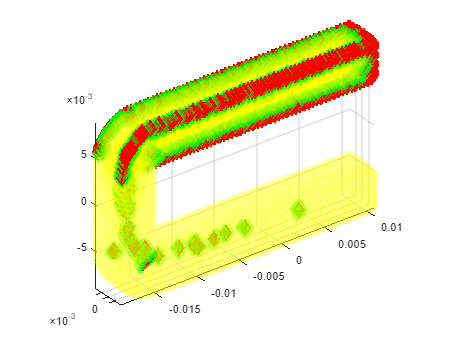

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs, normalsheardiffs, affectedelements)

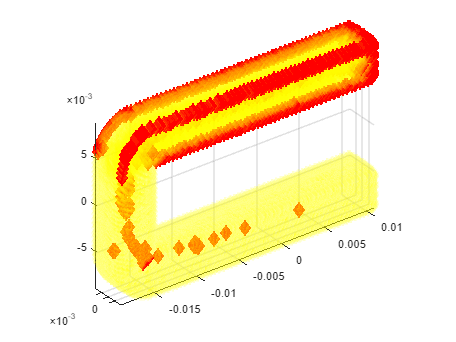

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs, normalsheardiffs, 0)

% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates_new = zeros(size(elementnodeids, 1), 3);
for i = 1:size(newelementnodeids, 1)
    columnids = newelementnodeids(i, :);
    x = mean(newnodepos(columnids, 1));
    y = mean(newnodepos(columnids, 2));
    z = mean(newnodepos(columnids, 3));
    elementcoordinates_new(i, :) = [x, y, z];
end

newelements = newelementnodeids(~ismember(newelementnodeids, elementnodeids, 'rows'), :)

newelements =        14234           5          22          32
       14234          35           5          32
       14495           9          44          41
       14495          45           9          41
       14498          17          52          61
       14498          52          17          62
       14498          19          17          61
       14498          17          19          62
       14053          25          18          17
       14053          18          62          17


oldelements = elementnodeids(~ismember(elementnodeids, elementnodeids(affectedelements, :), 'rows'), :)

oldelements =      1     2     3     4
     1     2     4     5
     5     4     1     6
     5     2     7     1
     8     6     1     4
     8     6     9     1
    11    10     3     1
    10    11    12     1
     1    10    13    14
     7    13    14     1


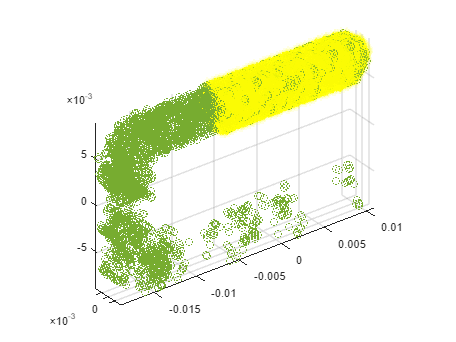


x = elementcoordinates_new(:, 1);
y = elementcoordinates_new(:, 2);
z = elementcoordinates_new(:, 3);
scatter3(x(oldelements), y(oldelements), z(oldelements), 100,  "filled", "d","y", 'MarkerFaceAlpha', 0.1,'MarkerEdgeAlpha', 0.2)
hold on
% scatter3(x(newelements), y(newelements), z(newelements), 100, 'filled', 'd', 'green', 'MarkerFaceAlpha', 0.5,'MarkerEdgeAlpha', 0.8)
scatter3(x(affectedelements), y(affectedelements), z(affectedelements))
axis equal

% hold off
